**Author: Clara Vetter**

**Last modified: 25.01.2024**

addpath(genpath("/Users/claravetter/local/Code/NeuroMiner/NeuroMiner_Current"))
addpath("~/local/Code/mbSPLS/ScrFun_CV/")

# Test script for generalized spls with simulated data - small example

## Simulated data

rng(42);

% Number of samples and features
numSamples = 10;
numFeaturesX = 15;
numFeaturesY = 20;
numFeaturesZ = 10;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

## Define sPLS parameters

% Sparsity regularization parameters
cu = 3;
cv = 4;
cw = 2;

% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

## cv_generalized_spls

matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances,success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);

SPLS: itr: 1001    diff: 4.21e-01    dim_M1: 1    dim_M2: 20    dim_M3: 10    


## Hyperopt

- Q: what is the optimisation criterion in this case? How can we define which multi weight vectors maximize covariance in the case that n matrices > 2

% define range of cu, cv, cw for grid search 
cu_range = 1:1:sqrt(size(matrices{1},2));
cv_range = 1:1:sqrt(size(matrices{2},2));
cw_range = 1:1:sqrt(size(matrices{3},2));

% run grid search 
combi_idx_xyz = 0;
combi_idx_xy = 0;
result_table_xyz_gspls = cell2table(cell(0,11), 'VariableNames',{'cu', 'cv', 'cw', 'corr_XY', 'corr_XZ', 'corr_YZ', 'spls_itr', 'diff', 'dim_m1', 'dim_m2', 'dim_m3'});
result_table_xy_spls = cell2table(cell(0,7), 'VariableNames',{'cu', 'cv', 'corr_XY', 'spls_itr', 'diff', 'dim_m1', 'dim_m2'});

for i=1:length(cu_range)
    for j=1:length(cv_range)
        for k=1:length(cw_range)
            cu = cu_range(i);
            cv = cv_range(j);
            cw = cw_range(k);
            combi_idx_xyz = combi_idx_xyz+1;
            cs = [cu, cv, cw];
            % Run generalized SPLS
            [weights, covariances, success, spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);
            corr_XY = corr(matrices{1}*weights{1},matrices{2}*weights{2});
            corr_XZ = corr(matrices{1}*weights{1},matrices{3}*weights{3});
            corr_YZ = corr(matrices{2}*weights{2},matrices{3}*weights{3});
            result_table_xyz_gspls.cu(combi_idx_xyz) = cu; 
            result_table_xyz_gspls.cv(combi_idx_xyz) = cv; 
            result_table_xyz_gspls.cw(combi_idx_xyz) = cw; 
            result_table_xyz_gspls.corr_XY(combi_idx_xyz) = corr_XY;
            result_table_xyz_gspls.corr_XZ(combi_idx_xyz) = corr_XZ;
            result_table_xyz_gspls.corr_YZ(combi_idx_xyz) = corr_YZ;
            result_table_xyz_gspls.spls_itr(combi_idx_xyz) = spls_itr; 
            result_table_xyz_gspls.diff(combi_idx_xyz) = diff; 
            result_table_xyz_gspls.dim_m1(combi_idx_xyz) = dim_Ms(1);
            result_table_xyz_gspls.dim_m2(combi_idx_xyz) = dim_Ms(2);
            result_table_xyz_gspls.dim_m3(combi_idx_xyz) = dim_Ms(3);
        end
        combi_idx_xy = combi_idx_xy+1;
        [u, v, success, spls_itr, diff, dim_Ms] = cv_spls(Y, Z, cv, cw, e, itr_lim, 0); 
        corr_XY = corr(Y*u, Z*v); 
        result_table_xy_spls.cu(combi_idx_xy) = cu; 
        result_table_xy_spls.cv(combi_idx_xy) = cv;
        result_table_xy_spls.corr_XY(combi_idx_xy) = corr_XY;
        result_table_xy_spls.spls_itr(combi_idx_xy) = spls_itr;
        result_table_xy_spls.diff(combi_idx_xy) = diff;
        result_table_xy_spls.dim_m1(combi_idx_xy) = dim_Ms(1);
        result_table_xy_spls.dim_m2(combi_idx_xy) = dim_Ms(2);
    end
end

## Weight updating pairwise spls vs. gspls

cv = 2; 
cw = 4;
[u,v,success,spls_itr, diff, dim_Ms] = cv_spls(Y,Z, cv, cw, e, 10, 2);

Initial u: -3.094103e-01 -1.222854e-01 -2.138600e-01 3.160309e-01 -1.372954e-01 -2.314881e-01 1.872054e-01 1.217159e-01 2.380454e-01 -4.059242e-03 1.804642e-01 3.369235e-03 -9.553819e-02 -4.620619e-01 2.663317e-01 2.180545e-01 2.559151e-01 -1.105565e-01 -3.321612e-01 5.464838e-02
Initial v: -2.301628e-01 -1.508696e-01 2.328182e-01 1.257323e-01 -6.911138e-01 -3.386781e-01 -3.343815e-01 -1.545862e-01 -3.219417e-01 -1.501837e-01

Iteration 0:
Updated u: -2.784857e-01 0 0 3.021196e-01 0 -3.229261e-04 0 0 2.373118e-02 0 0 0 0 -8.234136e-01 1.247060e-01 0 8.752124e-02 0 -3.597008e-01 0
Updated v: -3.177829e-01 -2.518247e-01 2.268789e-01 2.377071e-02 -6.392910e-01 -1.481246e-01 -3.648866e-01 -1.452627e-01 -3.747386e-01 -2.413563e-01

Iteration 1:
Updated u: -4.218212e-02 0 -1.461719e-01 3.351224e-01 0 0 0 0 5.159972e-03 0 0 0 0 -8.327130e-01 2.358513e-01 0 7.032648e-02 0 -3.324728e-01 0
Updated v: -3.144327e-01 -2.785236e-01 2.735682e-01 -1.349193e-02 -6.058605e-01 -1.583271e-02 -4.237003e-01

Iteration 10:
Updated u: 0 0 -2.302166e-02 2.337515e-01 0 0 0 0 0 0 0 0 0 -4.498790e-01 6.593254e-01 0 8.599585e-02 0 -5.480273e-01 0
Updated v: -9.754491e-02 -2.766879e-01 1.904441e-01 3.400874e-02 -5.885916e-01 4.005814e-02 -6.058925e-01 -8.185525e-02 -6.145430e-02 -3.884276e-01

SPLS: itr: 11    diff: 1.19e-02    dim_u: 6    dim_v: 10


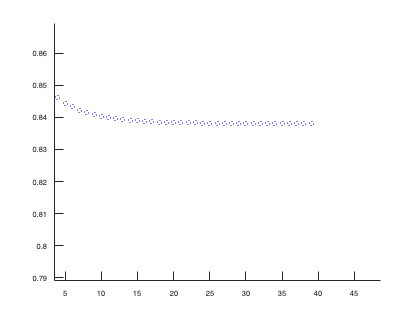

SPLS: itr: 44    diff: 9.31e-06    dim_M1: 5    dim_M2: 20    dim_M3: 10    


% Sparsity regularization parameters
cu = 2;
cv = 4;
cw = 4;
cs = [cu, cv, cw];
[u,v,success,spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, 10, 2);

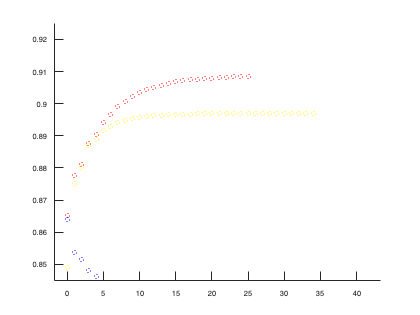

SPLS: itr: 44    diff: 9.31e-06    dim_M1: 5    dim_M2: 20    dim_M3: 10    
